# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 임진빈            **

**학번**** : 201918212**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

n = [-200:200];
x5n = 5*(cos(0.49*pi*n) + cos(0.51*pi*n));
figure(1), stem(n,x5n)
xlabel('n')
ylabel('x5n')
title('stem of function')

2) 

n = [0:100];
x7n = exp(-0.05*n).*sin(0.1*pi*n + pi/3);
figure(2), stem(n,x7n)
xlabel('n')
ylabel('x7n')
title('stem of function')


2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

n = [0:100]
a = [1 -0.5 0.25]; 
b = [1 2 0 1];  
hn = impz(b,a,n)
figure(3), stem(n,hn)
xlabel('n')
ylabel('hn')
title('stem of impulse response')


2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

n = [0:100]
a = [1 -0.5 0.25]; 
b = [1 2 0 1]; 
hn = impz(b,a,n);
abshn = abs(hn);
BIBO = sum(abshn);
BIBO



3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

n = [0:200];
a = [1 -0.5 0.25];
b = [1 2 0 1]; 
xn = ones(size(n)).*(5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)); 
yn = filter(b,a,xn)
figure(4), stem(n,yn)
xlabel('n')
ylabel('yn')
title('stem of response')

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n = [0:50];
yn = ((0.8).^(n+1) - (-0.9).^(n+1))/(1.7);
figure(4), stem(n,yn)
xlabel('n')
ylabel('yn')
title('stem of conv')

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n = [0:50];
xn = 0.8.^n;
nx = [0:50];
hn = (-0.9).^n;
nh = [0:50];
[yn,ny] = conv_m(xn,nx,hn,nh)
function [yn,ny] = conv_m(xn,nx,hn,nh)
ny1 = nx(1)+nh(1);
ny2 = nx(length(nx))+nh(length(nh));
ny = [ny1  : ny2];
yn = conv(xn, hn);
figure(5), stem(ny,yn)
xlabel('n')
ylabel('yn')
title('stem of conv using conv function')
end
%%%%%%%%%컨벌루션 까진 했는데 샘플을 자르는 것을 잘 못하겠습니다.


3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

%%%%잘 모르겠습니다.

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$ 

w = [-500*pi:500*pi];

스크립트의 함수 정의는 파일의 끝에 표시되어야 합니다.
"conv_m" 함수 정의 뒤에 있는 모든 명령문을 첫 번째 로컬 함수 정의 앞으로 이동하십시오.

k = 500;
w = w/k;
H = 0.19./(1.81-0.9*(exp(j*w)+exp(-j*w)));
magH = abs(H);
angH = angle(H)
figure(6), subplot(2,1,1), plot(w/pi, magH)
xlabel('w')
ylabel('magH')
title('magH of frequency function')
subplot(2,1,2), plot(w/pi, angH/pi)
axis([-1 1 -180 180])
xlabel('w')
ylabel('angH')
title('angle of frequency function')

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

w = [-500*pi:500*pi];
k = 500;
w = w/k;
H = (2-0.9*exp(-j*w))./(1-0.9*exp(-j*w)+0.2*exp(-2*j*w));
magH = abs(H);
angH = angle(H);
figure(7), subplot(2,1,1), plot(w/pi, magH)
xlabel('w')
ylabel('magH')
title('magH of frequency function')
subplot(2,1,2), plot(w/pi, 180*angH/pi)
xlabel('w')
ylabel('angH')
axis([-1 1 -180 180])
title('angle of frequency function')


5. (P3.17) 

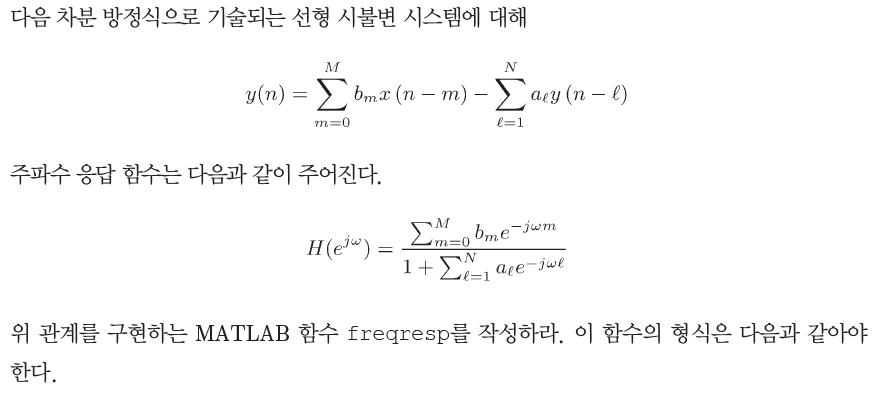

l = [0:N]
al = b.^l  %%%%%%% al을 a.^l이라 가정했습니다.
m = [0:M]
bm = a.^m  %%%%%%% bm을 b.^m이라 가정했습니다.
function [H] = freqresp(b,a,w)
w = [-500:500]*pi/500
a = al;
b = bl;
[H] = (b,a,w)
end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

w = [-500:500]*pi/500;
a = [1 -0.95 0.9025];
b = [1 0 -1];
m = [0:2];
n = [0 0 2];
Y = a*exp(-j*m'.*w);
X = b*exp(-j*n'.*w);
H = X./Y
magH = abs(H);
angH = angle(H);
figure(8), subplot(2,1,1), plot(w/pi, magH)
xlabel('w')
ylabel('magH')
title('magH of frequency function')
subplot(2,1,2), plot(w/pi, 180*angH/pi)
xlabel('w')
ylabel('angH')
axis([-1 1 -180 180])
title('angle of frequency function')


2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

w = [-500:500]*pi/500;
a = [1 0.5 (0.5)^2 (0.5)^3 (0.5)^4 (0.5)^5];
b = [1];
m = [0:5];
n = [1];
Y = a*exp(-j*m'.*w);
X = b*exp(-j*n *w);
H = X./Y
magH = abs(H);
angH = angle(H);
figure(8), subplot(2,1,1), plot(w/pi, magH)
xlabel('w')
ylabel('magH')
title('magH of frequency function')
subplot(2,1,2), plot(w/pi, 180*angH/pi)
xlabel('w')
ylabel('angH')
axis([-1 1 -180 180])
title('angle of frequency function')

